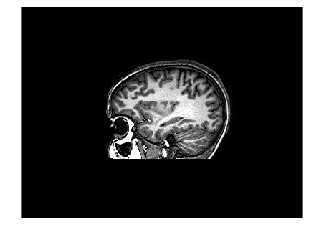

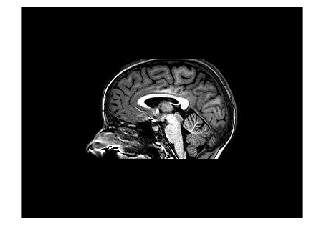

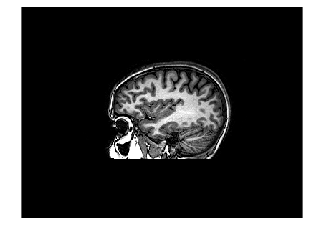

%call output_segmentation

%images=load("Images\Images.mat");

%read .png files from Images folder
files = dir('Images/AX_*.png');      % as example : only png files with "AX_" in the filename
% main loop
for ck = 1:length(files)
    Filename = files(ck).name;
    %read the image
    image{ck} = imread(Filename);
    %convert rgb to gray
    image{ck} = rgb2gray(image{ck});
    %convert to double
    image_AX{ck} = im2double(image{ck});

    % plot (t=just to check)
    figure(ck), imshow(image_AX{ck}); %imagesc only for png, now we converted it
    
    % insert your own code here
    
end


% %load images from dat
% first_image = images.AX(:,:,1);
% second_picture = images.COR(:,:,1);
% third_picture = images.SAG(:,:,1);

% image1 = im2double(first_image);
% image2 = im2double(second_picture);
% image3 = im2double(third_picture);

% figure(1)
% imshow(image1,[]);
% figure(2)
% imshow(image2,[]);
% figure(3)
% imshow(image3,[]);

%load image from individual PNG

% image_AX1 = imread('AX_1.png'); 
% image_AX1 = im2double(image_AX1);
% image_AX4 = imread('AX_4.png'); 
% image_AX4 = im2double(image_AX4);

figure(5)
imshow(image_AX{1},[]);

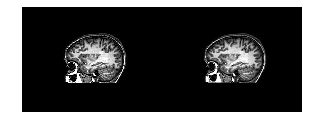


%extract background
%first apply gaussian smoothing

%Define an appropriate kernel HSIZE x HSIZE
HSIZE = 5; 
%Create an averaging filter H of size HSIZE
element = fspecial('average',HSIZE);

% Filter the noise using the above defined kernel
filtered_image = imfilter(image_AX{1},element);

figure(6)
imshowpair(image_AX{1},filtered_image,'montage')

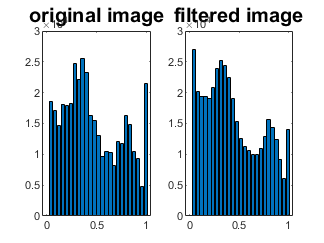

%Iblur1 = imgaussfilt(first_image,6);
%noisy_image = imnoise(first_image,'Gaussian',0, 0.01);

%filtered_image = imfilter(noisy_image,element);

%figure(7)
%imshow(filtered_image,[]);

%plotting histograms
[histogram1,bins] = hist(image_AX{1}(:),0:0.04:1);
[histogram2,bins] = hist(filtered_image(:),0:0.04:1);
histogram1(1)=0;
histogram2(1)=0;
figure(7)
subplot(1,2,1)
bar(bins,histogram1)
title('original image', 'FontSize', 15);
subplot(1,2,2)
bar(bins,histogram2)
title('filtered image', 'FontSize', 15);

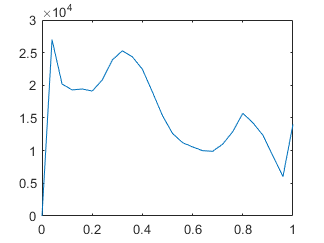


figure(8)
plot(bins,histogram2)

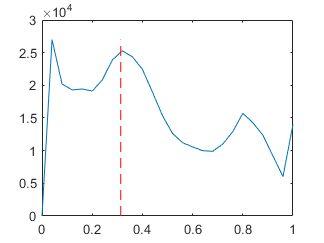


%using otsu_threshold for segmentation
otsu_threshold = graythresh(filtered_image);
BW = imbinarize(filtered_image,otsu_threshold);
% Calculate the histogram maximum value
max_histogram = max(histogram2); 

% Display the threshold on the histogram in a new figure by overlaying the histogram with a vertical line 
figure(8),
plot(bins,histogram2);
hold on;
plot([otsu_threshold otsu_threshold],[0 max_histogram],'--r'); % Add a vertical red (dashed) line.
hold off;

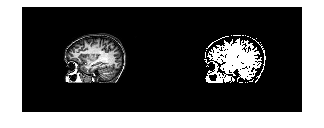


%show the binary image
figure(9)
imshowpair(filtered_image,BW,'montage')

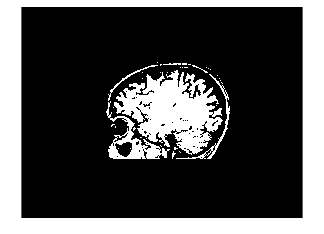



% Apply the thresholding
segmented_image = filtered_image > otsu_threshold; % segmented_image = ..

% Display the result in a new figure
figure(10)
imshow(segmented_image,[]);

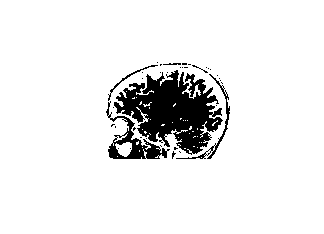


% Complement the image
complement_image = imcomplement(segmented_image); 

% Display the complement in a new figure
figure(11)
imshow(complement_image,[]);

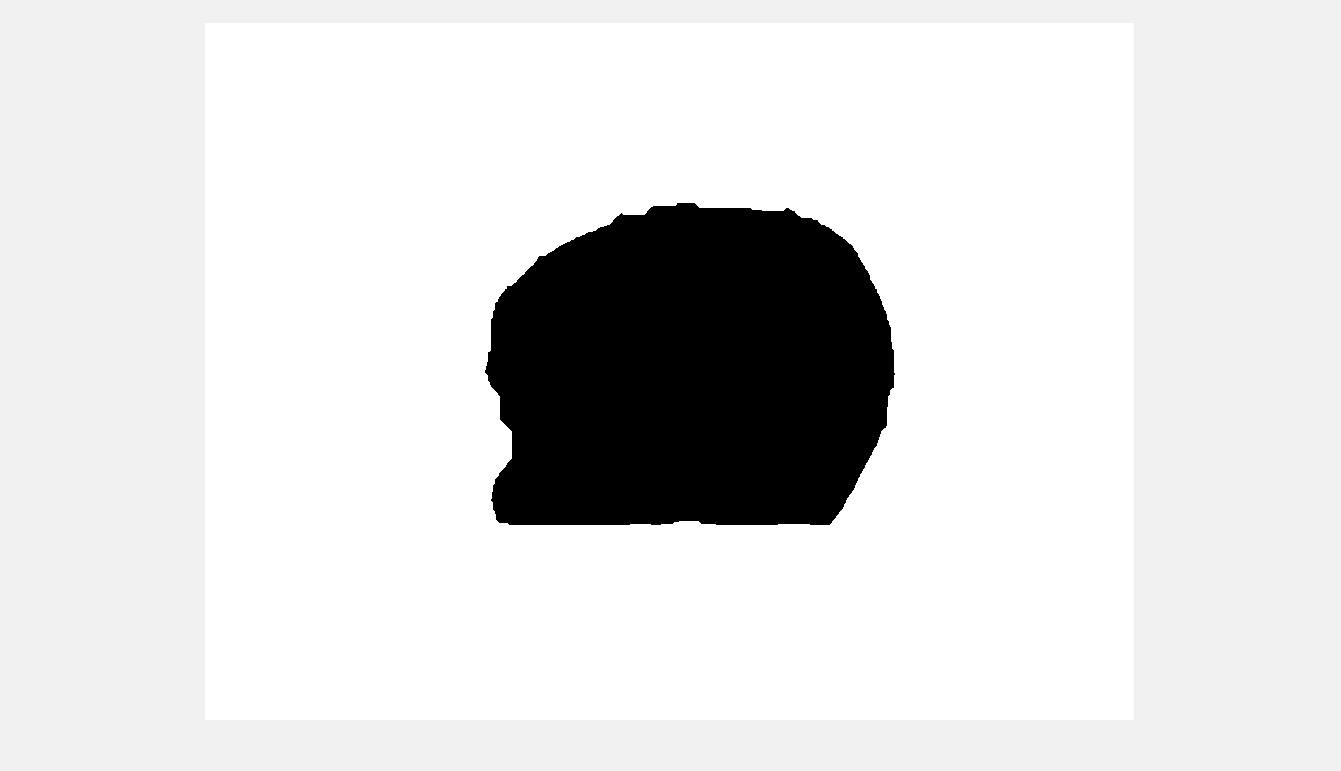


% Define an appropriate structuring element to fill the original segmentation
R = 44;
structuring_element = strel('disk',R);


% Perform the closing to fill the segmentated brain using the defined structuring element
% First clean the segmentation for small objects
segmented_image_clean = imopen(segmented_image,strel('disk',1));
brain_mask = imclose(segmented_image,structuring_element); 

% Complement the image
complement_image = imcomplement(brain_mask); 

% Display the brain_mask in a new figure
figure(12)
imshow(complement_image,[])

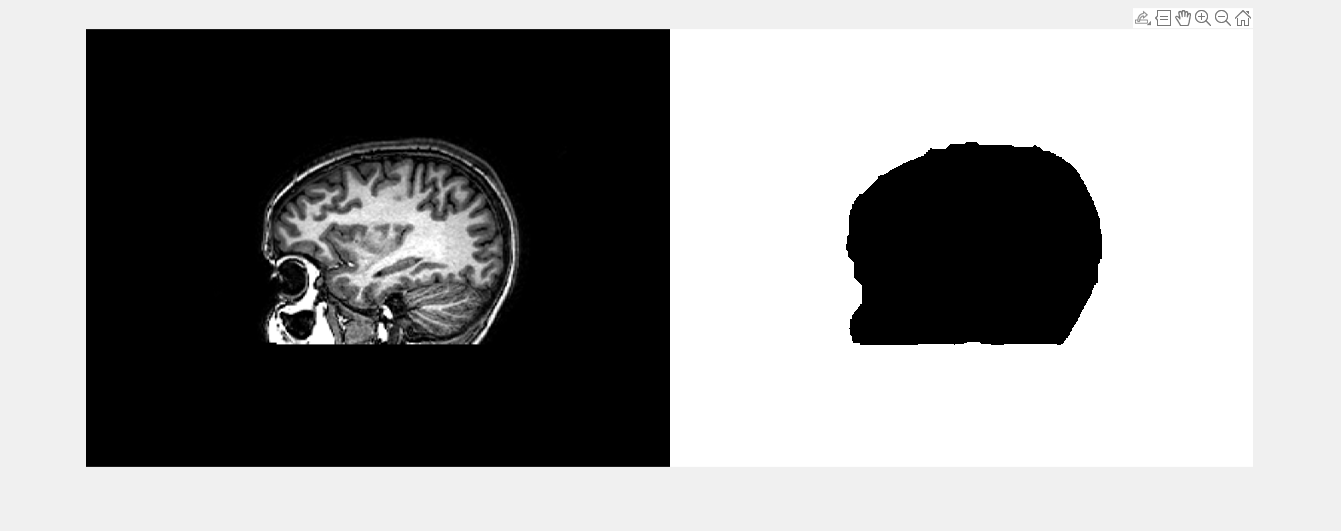

set(gcf,'Visible','on')


figure(13)
imshowpair(filtered_image,complement_image,'montage')
set(gcf,'Visible','on')

%apply rician noise
%im_r = ricernd(first_image, 5); % "Add" Rician noise (make Rician distributed)


% I1= imtophat(image1, strel('disk', 10));
% 
% figure, imshow(I1);
% T2= imadjust(I1);
% figure,imshow(image1);
% level=graythresh(image1);
% BW=imbinarize(image1,level);
% figure, imshow(BW);
% C=~BW;
% figure, imshow(C);
% D= -bwdist(C);
% 
% imshow(C)
% D(C)= -Inf;
% imshow(D)
% 
% L=watershed(D);
% Wi=label2rgb(L, 'hot', 'w');
% figure, imshow (Wi);
% % im= image1;
% % im(L==0)=0;
% % figure, imshow (im);
